**Box plots**

Single balloon

clf
Zdata = [Zreal(1:8000) data1aa(1001:9000,3) data1bb(1001:9000,3) data1cc(1001:9000,3) data1dd(1001:9000,3) data1ee(1001:9000,3) data1ff(1001:9000,3) data1gg(1001:9000,3) data1hh(1001:9000,3) data1ii(1001:9000,3)];
boxplot(Zdata,'Notch','off','Labels',{'Real world', 'a', 'b', 'c', 'd', 'e', 'f', 'g', 'h', 'i'});
title('Objective Functions: 1 Balloon')
xlabel({' ',' ','Model'})
ylabel('z (m)')
ylim([0 4]);

Collective balloon

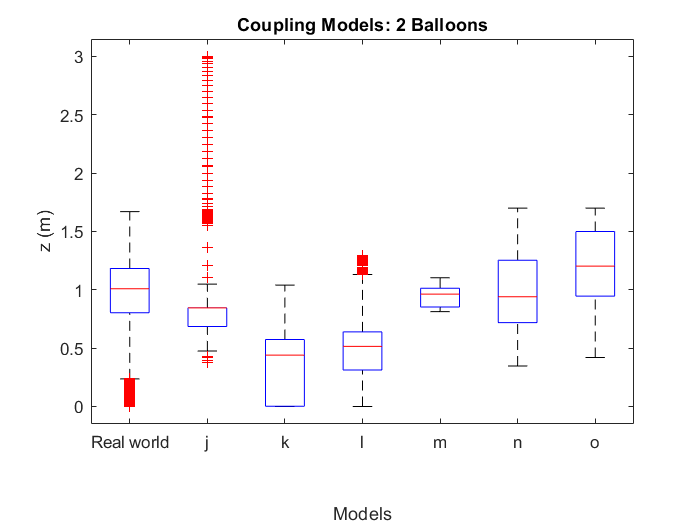

clf

% Zdata = [[Zreala(1:8000);Zrealb(1:8000)] [data2aa(1001:9000,3);data2aa(1001:9000,8)] [data2bb(1001:9000,3);data2bb(1001:9000,8)] [data2cc(1001:9000,3);data2cc(1001:9000,8)] [data2ll(1001:9000,3);data2ll(1001:9000,8)] [data2mm(1001:9000,3);data2mm(1001:9000,8)] [data2nn(1001:9000,3);data2nn(1001:9000,8)] [data2oo(1001:9000,3);data2oo(1001:9000,8)] [data2pp(1001:9000,3);data2pp(1001:9000,8)] [data2qq(1001:9000,3);data2qq(1001:9000,8)] [data2rr(1001:9000,3);data2rr(1001:9000,8)] [zeros(8000,1);zeros(8000,1)] [data2hh(1001:9000,3);data2hh(1001:9000,8)] [data2ii(1001:9000,3);data2ii(1001:9000,8)] [dataLeeA(1001:9000,3);dataLeeA(1001:9000,6)] [dataLeeB(1001:9000,3);dataLeeB(1001:9000,6)] [dataLeeC(1001:9000,3);dataLeeC(1001:9000,6)]];
Zdata = [[Zreala(1:8000);Zrealb(1:8000)] [data2aa(1001:9000,3);data2aa(1001:9000,8)] [data2bb(1001:9000,3);data2bb(1001:9000,8)] [data2cc(1001:9000,3);data2cc(1001:9000,8)] [dataLeeA(1001:9000,3);dataLeeA(1001:9000,6)] [dataLeeB(1001:9000,3);dataLeeB(1001:9000,6)] [dataLeeC(1001:9000,3);dataLeeC(1001:9000,6)]];
boxplot(Zdata,'Notch','off','Labels',{'Real world','j','k','l','m', 'n', 'o'});
title('Coupling Models: 2 Balloons')
xlabel({' ',' ','Models'})
ylabel('z (m)')

New way

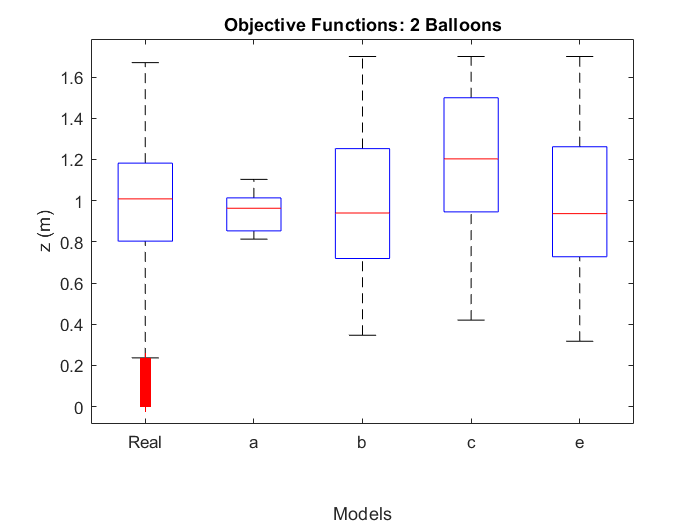

clf

Zdata = [[Zreala(1:8000);Zrealb(1:8000)] [dataLeeA(1001:9000,3);dataLeeA(1001:9000,6)] [dataLeeB(1001:9000,3);dataLeeB(1001:9000,6)] [dataLeeC(1001:9000,3);dataLeeC(1001:9000,6)] [dataLeeE(1001:9000,3);dataLeeE(1001:9000,6)]];
boxplot(Zdata,'Notch','off','Labels',{'Real','a', 'b', 'c', 'e'});
title('Objective Functions: 2 Balloons')
xlabel({' ',' ','Models'})
ylabel('z (m)')

**Behavioural breakdown barchart**

Single balloon

thresholdFalling = 0.5;

trajectory=Zreal;
% trajectory=data1c(:,3);

falling= 0;
stable= 0;

for i=1:30:8998;
%for i=1:40:12000;
    if trajectory(i) < thresholdFalling;
        falling = falling+1;
    else;
        stable = stable+1;
    end
end

classRef= [falling stable];

% clf
% figure(1)
% 
% lifecycles1 = [classRef; class1c; class1d]/3;

Unrecognized function or variable 'class1c'.

% fanPower= [0 1 2];
% 
% b= bar(fanPower, lifecycles1', 'stacked');
% title('Behavioural breakdown');
% xlabel('Model');
% ylabel('Time exhibiting behaviour');
% legend('Falling', 'Stable');
% ylim([0 100]);

Collective balloon

% thresholdFalling = 0.5;
% thresholdInteracting = 2*rb;
% 
% trajectory1=Ztest(:,1);
% trajectory2=Ztest(:,2);
% 
% % trajectory1=Zreala;m
% % trajectory2=Zrealb;
% 
% falling= 0;
% interacting= 0;
% stable= 0;
% 
% % for i=1:30:8998;
% for i=1:40:12000;
%     if trajectory1(i) < thresholdFalling || trajectory2(i) < thresholdFalling;
%         falling = falling+1;
%     elseif abs(trajectory1(i)-trajectory2(i))<thresholdInteracting;
%         interacting = interacting+1;
%     else;
%         stable = stable+1;
%     end
% end
% 
% classSim= [falling interacting stable];

% lifecycles = [classRef; classSim];
% fanPower= [0 1];
% 
% b= bar(fanPower, lifecycles', 'stacked');
% title('Behavioural breakdown');
% xlabel('Model');
% ylabel('Time exhibiting behaviour');
% legend('Falling', 'Interacting', 'Stable');

**Mean lifecycle length**

% Split into lifecycles with falling areas as the breakpoint
V = classOrder;
idx = [find(V == 1) length(V)+1];                           % Find falling areas & end indices
didx = diff([0 idx])-1;                                     % Lifecycle lengths
V0 = V;                                                     % Create ‘V0’ (duplicate of ‘V’)
V0(V0 == 1) = [];                                           % Delete falling areas
C = mat2cell(V0, 1, didx);                                  % Create cell array
lifecycles = C(cellfun(@(x) size(x,2)~=0, C));              % Delete empty cells
lifecycles=lifecycles';                                     % 'Lifecycles' contains the behavioural composition for each lifecycle

% Find mean lifecycle length

lifetimes=[];

for i=1:size(lifecycles,1)
    lifetimes(i)=length(lifecycles{i, 1});
end

lifetimes=mean(lifetimes);

**Comparison of XYZ of real and model for single balloon**

Single balloon

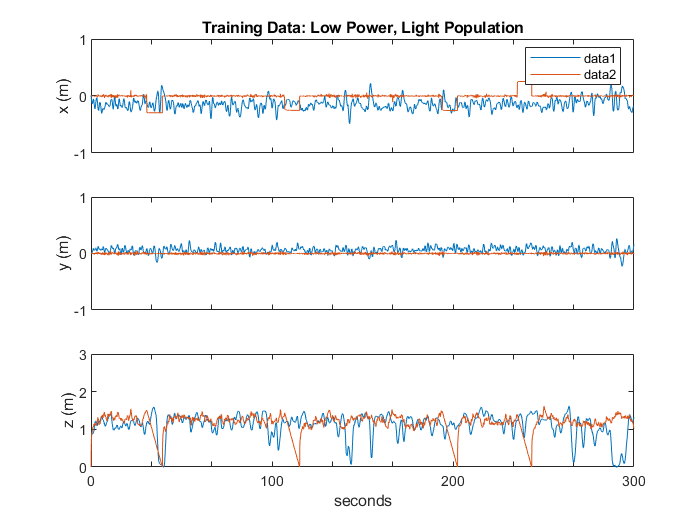

clf 

subplot(3,1,1);
plot(T_18_0(:,1));
ylabel('x (m)');
set(gca, 'XTickLabel',[]);
ylim([-1 1]);
title('Training Data: Low Power, Light Population');
legend
hold on;
plot(data1cc(1:9000,1));
hold off;

subplot(3,1,2);
plot(T_18_0(:,2));
ylabel('y (m)');
set(gca, 'XTickLabel',[]);
ylim([-1 1]);
hold on;
plot(data1cc(1:9000,2));
hold off;

subplot(3,1,3);
plot(T_18_0(:,3));
ylabel('z (m)');
xticks([0 1000 2000 3000 4000 5000 6000 7000 8000 9000 10000]);
xticklabels({'0', ' ', ' ', '100', ' ', ' ', '200', ' ', ' ', '300'});
xlabel('seconds');
ylim([0 3]);
hold on;
plot(data1cc(1:9000,3));
hold off;

Same

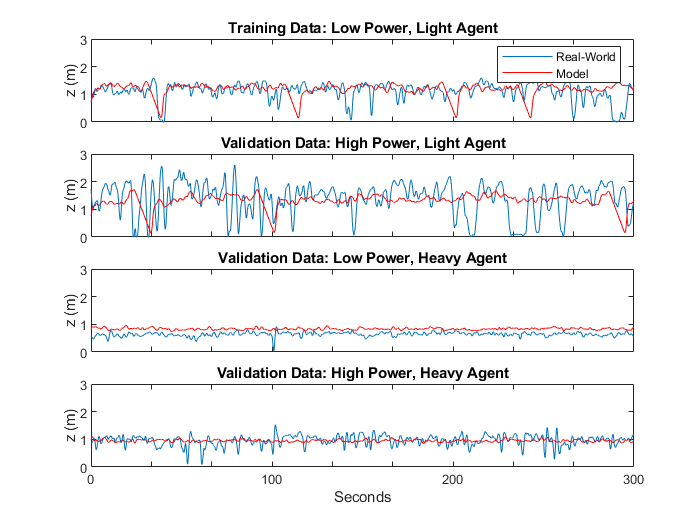

clf 

subplot(4,1,1);
plot(T_18_0(:,3));
ylabel('z (m)');
set(gca, 'XTickLabel',[]);
ylim([0 3]);
title('Training Data: Low Power, Light Agent');
legend
hold on;
new = smoothdata(data1cc,'gaussian',70);
% new = data1cc;
plot(new(1:9000,3), 'r');
legend('Real-World', 'Model')
hold off;

subplot(4,1,2);
plot(T_22_0(:,3));
ylabel('z (m)');
set(gca, 'XTickLabel',[]);
ylim([0 3]);
title('Validation Data: High Power, Light Agent');
hold on;
new = smoothdata(data1_22_0,'gaussian',70);
% new = data1_22_0;
plot(new(1:9000,3),'r');
hold off;

subplot(4,1,3);
plot(T_18_3(:,3));
ylabel('z (m)');
set(gca, 'XTickLabel',[]);
ylim([0 3]);
title('Validation Data: Low Power, Heavy Agent');
hold on;
new = smoothdata(data1_18_3,'gaussian',70);
plot(new(1:9000,3),'r');
hold off;

subplot(4,1,4);
plot(T_22_3(:,3));
ylabel('z (m)');
set(gca, 'XTickLabel',[]);
ylim([0 3]);
title('Validation Data: High Power, Heavy Agent');
hold on;
new = smoothdata(data1_22_3,'gaussian',70);
plot(new(1:9000,3),'r');
xticks([0 1000 2000 3000 4000 5000 6000 7000 8000 9000 10000]);
xticklabels({'0', ' ', ' ', '100', ' ', ' ', '200', ' ', ' ', '300'});
xlabel('Seconds');
hold off;

XYZ comparison for dual

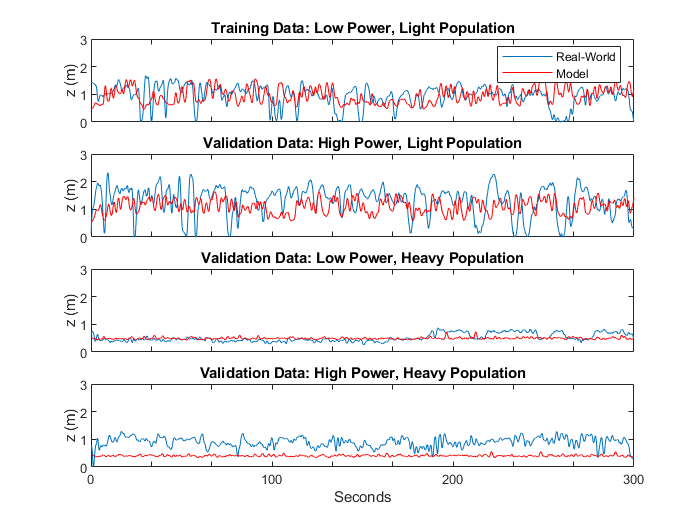

clf 

subplot(4,1,1);
plot(T_18_00(:,3));
ylabel('z (m)');
set(gca, 'XTickLabel',[]);
ylim([0 3]);
title('Training Data: Low Power, Light Population');
legend
hold on;
new = smoothdata(dataLeeB,'gaussian',70);
plot(new(1:9000,3), 'r');
legend('Real-World', 'Model')
hold off;

subplot(4,1,2);
plot(T_22_00(:,6));
ylabel('z (m)');
set(gca, 'XTickLabel',[]);
ylim([0 3]);
title('Validation Data: High Power, Light Population');
hold on;
new = smoothdata(dataLeeB0022,'gaussian',70);
plot(new(1:9000,3),'r');
hold off;

subplot(4,1,3);
plot(T_18_33(:,6));
ylabel('z (m)');
set(gca, 'XTickLabel',[]);
ylim([0 3]);
title('Validation Data: Low Power, Heavy Population');
hold on;
new = smoothdata(dataLeeB3318,'gaussian',70);
plot(new(1:9000,6),'r');
hold off;

subplot(4,1,4);
plot(T_22_33(:,3));
ylabel('z (m)');
set(gca, 'XTickLabel',[]);
ylim([0 3]);
title('Validation Data: High Power, Heavy Population');
hold on;
new = smoothdata(dataLeeB3322,'gaussian',70);
plot(new(1:9000,3),'r');
xticks([0 1000 2000 3000 4000 5000 6000 7000 8000 9000 10000]);
xticklabels({'0', ' ', ' ', '100', ' ', ' ', '200', ' ', ' ', '300'});
xlabel('Seconds');
hold off;

Anisotropic validation

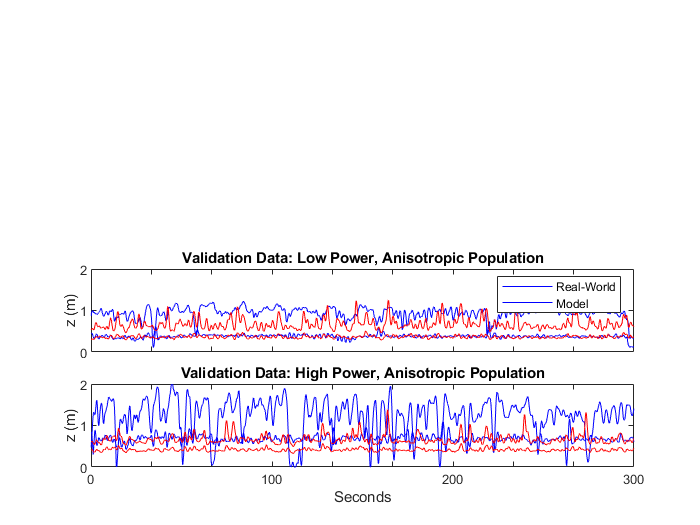

clf

subplot(2,1,1);
plot(T_18_15(:,3), 'b');
ylabel('z (m)');
set(gca, 'XTickLabel',[]);
ylim([0 2]);
title('Validation Data: Low Power, Anisotropic Population');
legend
hold on;
plot(T_18_15(:,6), 'b');
new = smoothdata(dataLee1518,'gaussian',70);
plot(new(1:9000,3), 'r');
plot(new(1:9000,6), 'r');
legend('Real-World', 'Model')
hold off;

subplot(2,1,2);
plot(T_22_15(:,3),'b');
ylabel('z (m)');
set(gca, 'XTickLabel',[]);
ylim([0 2]);
title('Validation Data: High Power, Anisotropic Population');
hold on;
plot(T_22_15(:,6), 'b');
new = smoothdata(dataLee1522,'gaussian',70);
plot(new(1:9000,3), 'r');
plot(new(1:9000,6), 'r');
xticks([0 1000 2000 3000 4000 5000 6000 7000 8000 9000 10000]);
xticklabels({'0', ' ', ' ', '100', ' ', ' ', '200', ' ', ' ', '300'});
xlabel('Seconds');
hold off;

Collective balloon

clf

title('Height trajectories for collective Bernoulli-ball models')
subplot(5,1,1);
plot(Zreala);
title('Real world data')
ylim([0 3]);
hold on
plot(Zrealb);
hold off

subplot(5,1,2);
plot(data2a(1:9000,3));
title('Inherited parameters')
ylim([0 3]);
hold on
plot(data2a(1:9000,8));
hold off

subplot(5,1,3);
%ZTest11 = smoothdata(ZTest1,'gaussian',70);
plot(data2b(1:9000,3));
title('No inheritance')
ylim([0 3]);
hold on
plot(data2b(1:9000,8));
hold off

subplot(5,1,4);
%Z2222 = smoothdata(Z3newnew,'gaussian',70);
plot(data2c(1:9000,3));
title('No inheritance')
ylim([0 3]);
hold on
plot(data2c(1:9000,8));
hold off

subplot(5,1,5);
%Z2222 = smoothdata(Z3newnew,'gaussian',70);
plot(data2d(1:9000,3));
title('No inheritance')
ylim([0 3]);
hold on
plot(data2d(1:9000,8));
hold off

**Noise and horizontal position**

subplot(2,1,1)
plot(data1b(:,1))
title('Horizontal displacement')

subplot(2,1,2)
plot(data1b(:,4))
title('Horizontal force')

**Transition Diagrams**

1 balloon


DataA=smoothedData_A_18_0;
DataB=smoothedData_B_18_0;

nb=1;
ID=1;

clf

BarVec = [];

traj3D
    
    
    XX=X;
    YY=Y;
    ZZ=Z;
    
    detectFalling;
    detectInteracting;
    
    ZFallingMarkov=[];
    ZInteractingMarkov=[];
    ZZMarkov = [];
    
    for k=2:length(ZFalling)
        if min(isnan(ZFalling(k,:)))==1
            ZZMarkov(end+1,:)=ZZ(k,:);
            ZFallingMarkov(end+1,:)=ZFalling(k,:);
            ZInteractingMarkov(end+1,:)=ZInteracting(k,:);
        elseif min(isnan(ZFalling(k,:)))==0 && min(isnan(ZFalling(k-1,:)))==1
            ZZMarkov(end+1,:)=ZZ(k,:);
            ZFallingMarkov(end+1,:)=ZFalling(k,:);
            ZInteractingMarkov(end+1,:)=ZInteracting(k,:); 
        end 
    end
    
    for i=1 %:cls
        G=graphs{i};
        h=plot(G,'Layout','circle','NodeColor','r','LineWidth',3,'EdgeLabel',G.Edges.Weight);

    h.EdgeLabel
    
    end

2 balloons

trajectory1=T_18_00(:,3);

trajectory1 =     1.4324
    1.4322
    1.4320
    1.4317
    1.4314
    1.4310
    1.4306
    1.4302
    1.4297
    1.4292


trajectory2=T_18_00(:,6);

trajectory2 =     1.0243
    1.0226
    1.0204
    1.0177
    1.0146
    1.0113
    1.0079
    1.0046
    1.0013
    0.9981



falling= 0;
interacting= 0;
stable= 0;

classOrder = [];


classOrder =

     []




for i=1:30:8998;
    if trajectory1(i) < thresholdFalling || trajectory2(i) < thresholdFalling;
        falling = falling+1;
        classOrder(i) = 1;
    elseif abs(trajectory1(i)-trajectory2(i))<thresholdInteracting;
        interacting = interacting+1;
        classOrder(i) = 2;
    else;
        stable = stable+1;
        classOrder(i) = 3;
    end
end

classOrder=nonzeros(classOrder)';

classOrder =      3     3     3     3     3     3     3     3     3     3     3     3     2     3     3     3     3     1     1     1     1     2     3     3     3     3     2     1     1     3     3     3     3     1     1     3     1     3     3     3     3     1     2     3     3     3     3     3     3     2



class= [falling interacting stable];

class =     66    64   170



% Create state transition probability matrix 

seqCount = zeros(3,3);
for i=1:3
for j=1:3
    seqCount(i,j)= sum(strfind(classOrder,[i j])~=0)/(numel(classOrder)-1);
end
end

transitionMatrix = bsxfun(@rdivide,seqCount,sum(seqCount,2));

transitionMatrix =     0.5846    0.1077    0.3077
    0.1406    0.3125    0.5469
    0.1118    0.2176    0.6706



markovChain = dtmc(transitionMatrix);

markovChain =   dtmc with properties:

             P: [3×3 double]
    StateNames: ["1"    "2"    "3"]
     NumStates: 3


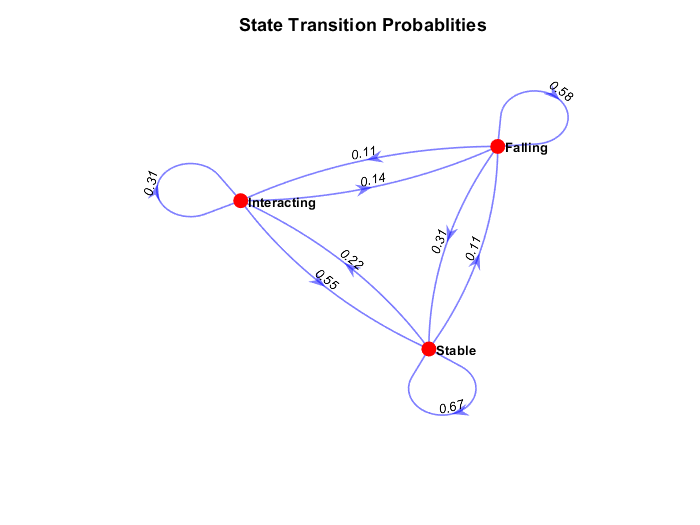

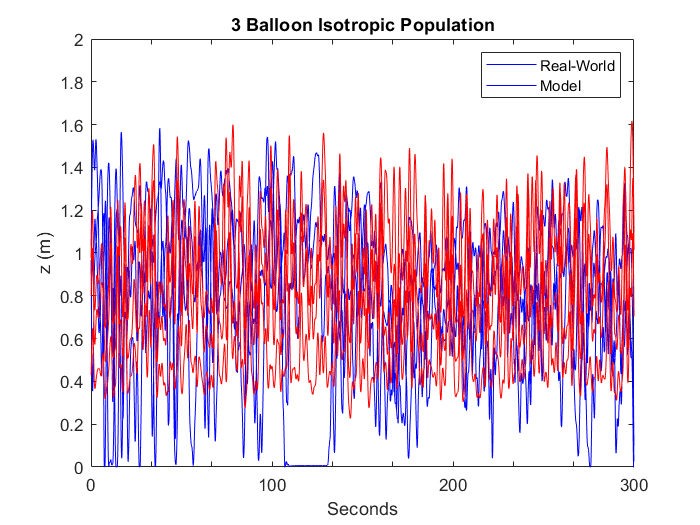

stateNames = ["Falling" "Interacting" "Stable"];
markovChain.StateNames = stateNames;
figure;
graphplot(markovChain, 'LabelEdges', true);
title('State Transition Probablities')

4 sim only

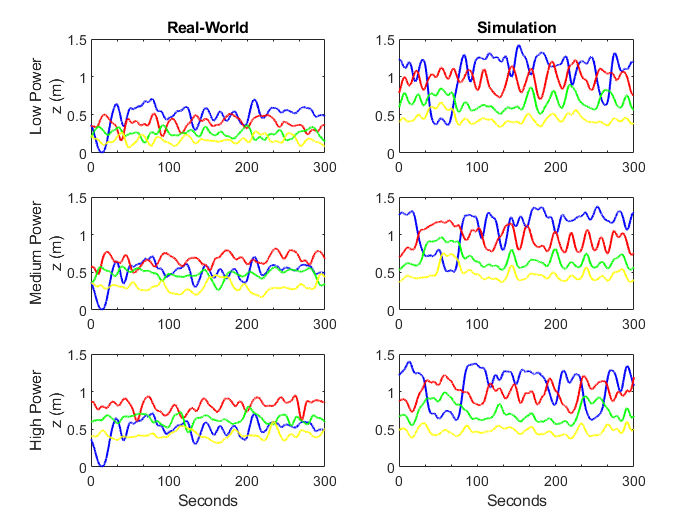

clf

subplot(3,2,1)
T_18_1357s = smoothdata(T_18_1357,'gaussian',500);
plot(T_18_1357s(:,3),'b', 'LineWidth',1.2);
ylabel({'Low Power','z (m)'});
set(gca, 'XTickLabel',[]);
ylim([0 1.5]);
title('Real-World');
hold on;
plot(T_18_1357s(:,6),'r', 'LineWidth',1.2);
plot(T_18_1357s(:,9),'g', 'LineWidth',1.2);
plot(T_18_1357s(:,12),'y', 'LineWidth',1.2);
xlim([0 9000])
xticks([0 1000 2000 3000 4000 5000 6000 7000 8000 9000]);
xticklabels({'0', ' ', ' ', '100', ' ', ' ', '200', ' ', ' ', '300'});
hold off;
subplot(3,2,2)
new = smoothdata(dataLee4,'gaussian',500);
% new = new-0.4;
plot(new(1:9000,3), 'b', 'LineWidth',1.2);
set(gca, 'XTickLabel',[]);
ylim([0 1.5]);
title('Simulation');
hold on;
plot(new(1:9000,6), 'r', 'LineWidth',1.2);
plot(new(1:9000,9), 'g', 'LineWidth',1.2);
plot(new(1:9000,12), 'y', 'LineWidth',1.2);
xlim([0 9000])
xticks([0 1000 2000 3000 4000 5000 6000 7000 8000 9000]);
xticklabels({'0', ' ', ' ', '100', ' ', ' ', '200', ' ', ' ', '300'});
hold off;


subplot(3,2,3)
T_20_1357s = smoothdata(T_20_1357,'gaussian',500);
plot(T_18_1357s(:,3),'b', 'LineWidth',1.2);
ylabel({'Medium Power','z (m)'});
set(gca, 'XTickLabel',[]);
ylim([0 1.5]);
hold on;
plot(T_20_1357s(:,6),'r', 'LineWidth',1.2);
plot(T_20_1357s(:,9),'g', 'LineWidth',1.2);
plot(T_20_1357s(:,12),'y', 'LineWidth',1.2);
xlim([0 9000])
xticks([0 1000 2000 3000 4000 5000 6000 7000 8000 9000]);
xticklabels({'0', ' ', ' ', '100', ' ', ' ', '200', ' ', ' ', '300'});
hold off;
subplot(3,2,4)
new1 = smoothdata(dataLee420,'gaussian',500);
% new1 = new1-0.4;
plot(new1(1:9000,3), 'b', 'LineWidth',1.2);
set(gca, 'XTickLabel',[]);
ylim([0 1.5]);
hold on;
plot(new1(1:9000,6), 'r', 'LineWidth',1.2);
plot(new1(1:9000,9), 'g', 'LineWidth',1.2);
plot(new1(1:9000,12), 'y', 'LineWidth',1.2);
xlim([0 9000])
xticks([0 1000 2000 3000 4000 5000 6000 7000 8000 9000]);
xticklabels({'0', ' ', ' ', '100', ' ', ' ', '200', ' ', ' ', '300'});
hold off;

subplot(3,2,5)
T_22_1357s = smoothdata(T_22_1357,'gaussian',500);
plot(T_18_1357s(:,3),'b', 'LineWidth',1.2);
ylabel({'High Power','z (m)'});
set(gca, 'XTickLabel',[]);
ylim([0 1.5]);
hold on;
plot(T_22_1357s(:,6),'r', 'LineWidth',1.2);
plot(T_22_1357s(:,9),'g', 'LineWidth',1.2);
plot(T_22_1357s(:,12),'y', 'LineWidth',1.2);
xlim([0 9000])
xticks([0 1000 2000 3000 4000 5000 6000 7000 8000 9000]);
xticklabels({'0', ' ', ' ', '100', ' ', ' ', '200', ' ', ' ', '300'});
xlabel('Seconds');
hold off;
subplot(3,2,6)
new2 = smoothdata(dataLee422,'gaussian',500);
% new1 = new1-0.4;
plot(new2(1:9000,3), 'b', 'LineWidth',1.2);
set(gca, 'XTickLabel',[]);
ylim([0 1.5]);
hold on;
plot(new2(1:9000,6), 'r', 'LineWidth',1.2);
plot(new2(1:9000,9), 'g', 'LineWidth',1.2);
plot(new2(1:9000,12), 'y', 'LineWidth',1.2);
xlim([0 9000])
xticks([0 1000 2000 3000 4000 5000 6000 7000 8000 9000]);
xticklabels({'0', ' ', ' ', '100', ' ', ' ', '200', ' ', ' ', '300'});
xlabel('Seconds');
hold off;